function [C_L, C_D] = supersonicShockwave_Sweep(AoA, Ma, Tau, sweepAngle)
    C_L = supersonicShockwaveLift_Sweep(AoA, Ma, sweepAngle);
    C_D = supersonicShockwaveDrag_Sweep(AoA, Ma, Tau, sweepAngle);
end

# Supersonic Wing Sweep Correction - Basic Theory

(Based on top of supersonicShockwave.mlx)

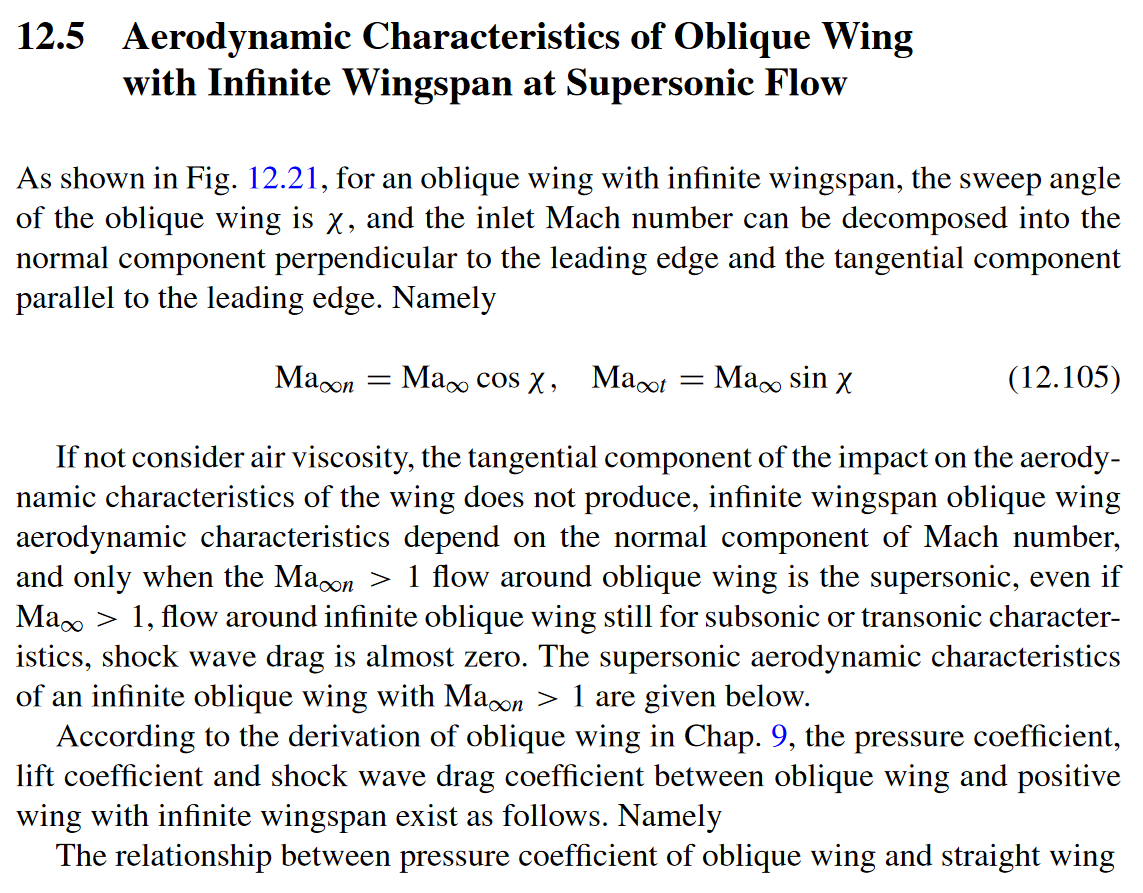

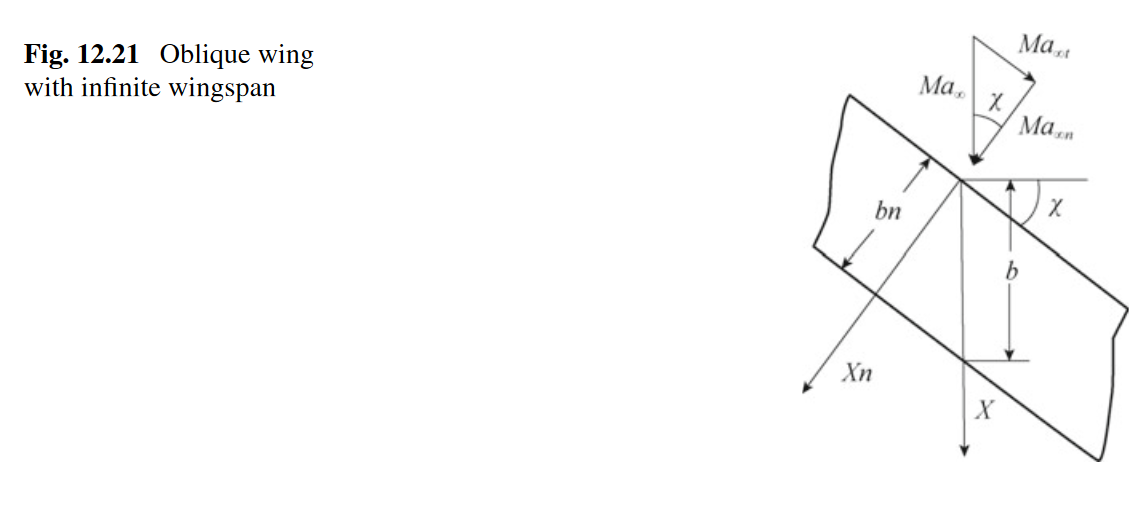

[P. Liu, Aerodynamics, [https://doi.org/10.1007/978-981-19-4586-1_12]](https://doi.org/10.1007/978-981-19-4586-1_12])

# Limitations:

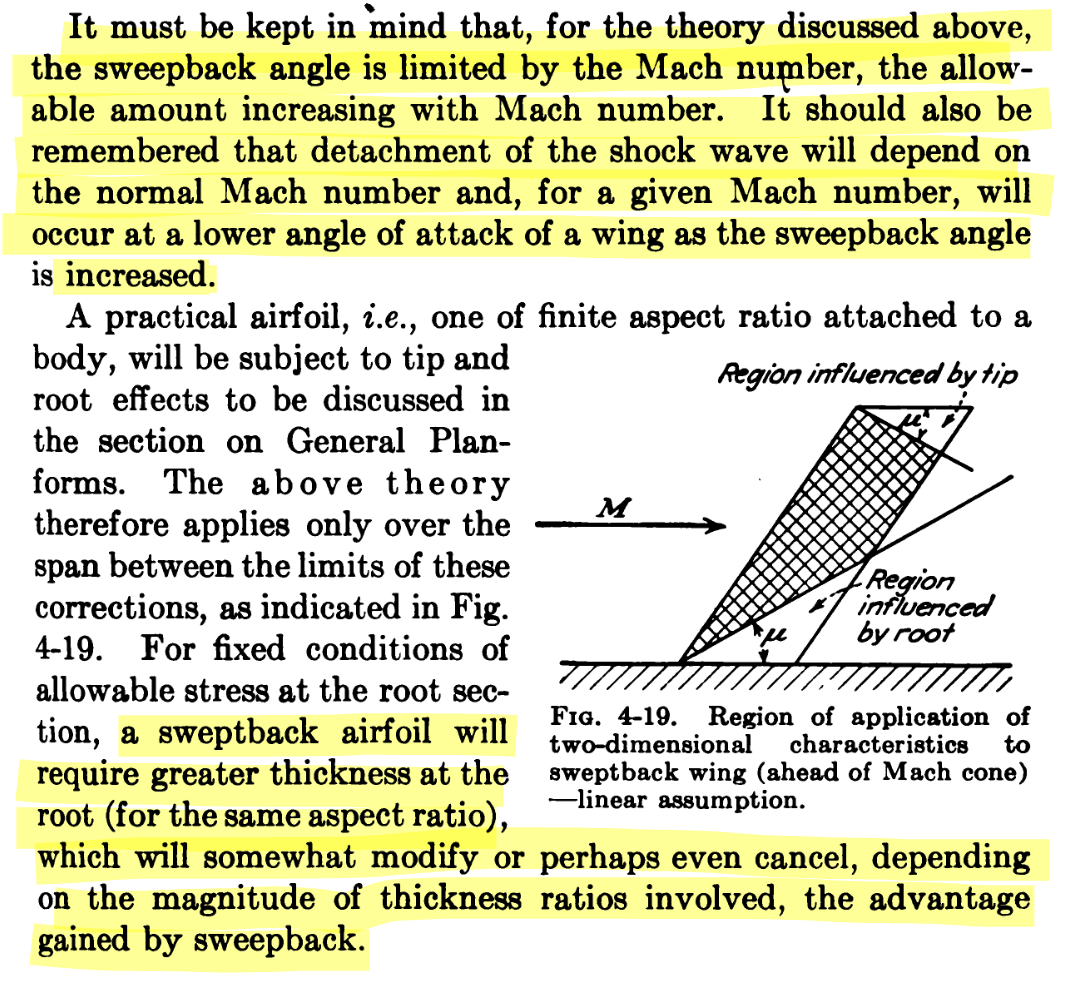

[E. Arthur Bonney - Engineering Supersonic Aerodynamics P. 135]

# Supersonic Wing Sweep Correction - Lift

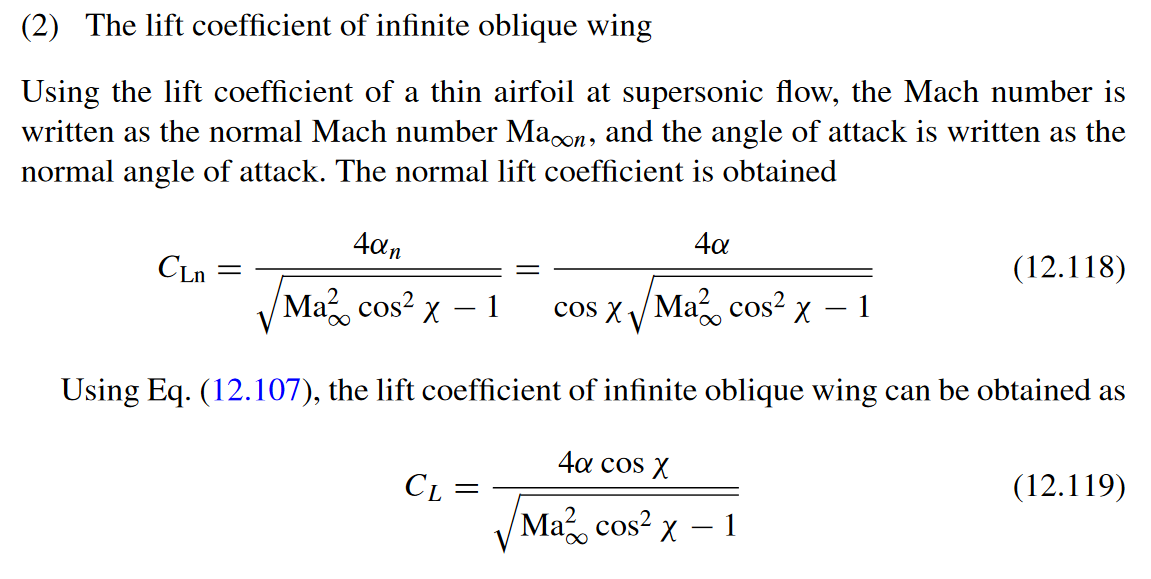

[P. Liu, Aerodynamics, [https://doi.org/10.1007/978-981-19-4586-1_12]](https://doi.org/10.1007/978-981-19-4586-1_12])

function C_L = supersonicShockwaveLift_Sweep(AoA, Ma, sweepAngle)
%Lift Coefficient due to supersonic shock wave for any thin fin profile:
fprintf("supersonicShockwaveLift() assumes: \n\t - attached supersonic flow (low AoA, Ma) \n\t - thin flat plate airfoil \n\t - infinite wing span \n");

    if AoA > 7
        warndlg("Warning: Angle of Attack (AoA) is more than 7°, Linear Lift Theory assumes attached flow and low AoA", "supersonicShockwaveLift()");
    end

    if Ma > 2
        warndlg("Warning: Mach Number (Ma) is above 2, Linear Lift Theory assumes supersonic attached flow. (for hypersonic flow use 'Newtonian Impact Theory')", "supersonicShockwaveLift()");
    end
    C_L = 4*(AoA*pi/180)*cosd(sweepAngle)/sqrt(Ma^2*cosd(sweepAngle)^2-1);
end

# Supersonic Wing Sweep Correction - Shock Wave Drag (Form Drag)

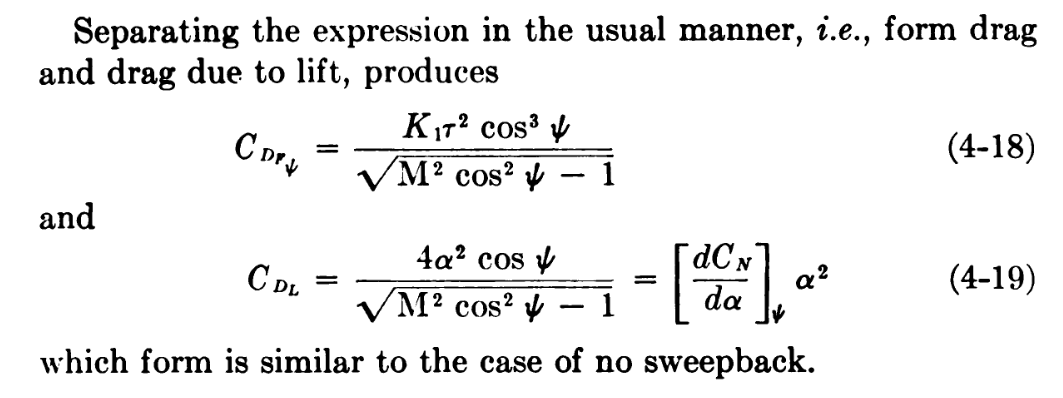

[E. Arthur Bonney - Engineering Supersonic Aerodynamics P. 134]

function C_D = supersonicShockwaveDrag_Sweep(AoA, Ma, Tau, sweepAngle)
%Drag Coefficient due to supersonic shock wave for diamond shaped profile with sweep:
% Tau ... diamond airfoil half angle "τ"
    AoA_rad = AoA*pi/180;
    Tau_rad = Tau*pi/180;
    C_D=4*(Tau_rad^2*cosd(sweepAngle)^3)/sqrt(Ma^2*cosd(sweepAngle)^2-1);
end

## Comment on P. Liu Source on Sweepback:

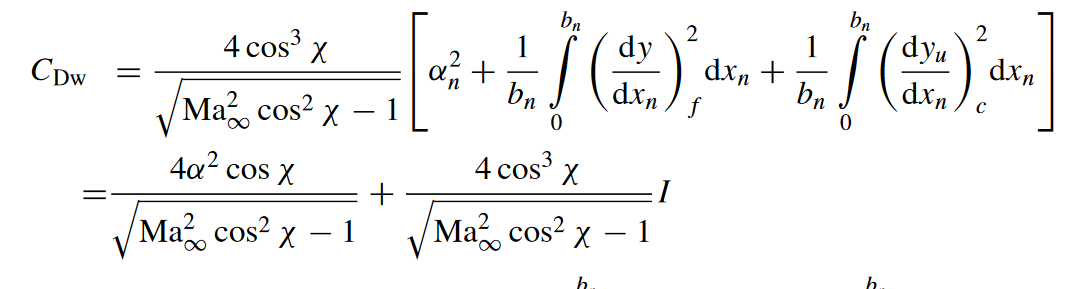

[P. Liu, Aerodynamics, [https://doi.org/10.1007/978-981-19-4586-1_12]](https://doi.org/10.1007/978-981-19-4586-1_12])